# Lab session II:

## Intro:

On this Laboratory session we are going to work with the different attitude representations seen in class. 

- Exercise 1: 1 point. To be delivered before the end of the session.

- Exercise 2: 2 points

- Exercise 3: 2.5 points

- Exercise 4: 2 points

- Exercise 5: 2.5 points

**Lab rules:**

- Always respect the delivery dates

- Use the templates when provided and DO NOT MODIFY THE FILE NAMES OR THE FUNCTION NAMES

- Verify that your code works before submit

- Always upload the files in a .zip with the name structure:  * Surname_Name.zip*

- Cheating is not allowed and will be firmly punished with a final mark of 0

This assignment is due to Sunday 19th before 23:45 p.m.

## Exercise 1:

**Create** and **test** a function named **Eaa2rotMat **that given euler axis/angle information returns the respective rotation matrix.

Perform and show the result of the next verifications:

- Calculate the determinant of the resulting rotation matrix 

Eaa2rotMat([1;0;0],2*pi)

ans =     1.0000         0         0
         0    1.0000    0.0000
         0   -0.0000    1.0000


det(ans)

ans = 1

- Compare the transpose and the inverse of the resulting matrix

ans'

ans = 1

inv(ans)

ans = 1

%Tant la inversa com la transposada són 1

- Using the output matrix, transform a vector parallel to the axis of rotation. 

r_mat=Eaa2rotMat([0;0;1],pi/4)

r_mat =     0.7071   -0.7071         0
    0.7071    0.7071         0
         0         0    1.0000


vec=[0;0;5]

vec =      0
     0
     5


r_mat*vec

ans =      0
     0
     5


What happens?

    El vector queda igual que al principi. Això es degut a que al ser un vector paralel a l'eix de rotació, la seva transformació   serà igual que l'eix.

- Using the output matrix, transform a vector perpendicular to the axis direction. Calculate the escalar product between the original  vector and the transformed one.

r_mat

r_mat =     0.7071   -0.7071         0
    0.7071    0.7071         0
         0         0    1.0000


vec1=[0;1;0]

vec1 =      0
     1
     0


r_mat*vec1

ans =    -0.7071
    0.7071
         0


dot(vec1,ans)

ans = 0.7071

 What you observe?

    El producte escalar es igual al cosinus de l'angle al que rotem l'eix.

## Exercise 2:

The matrix 

axisM = (rand(3,100)-.5)

axisM =    -0.0521    0.0314   -0.0296   -0.0575    0.4504    0.0548    0.2523   -0.3691   -0.4711    0.1090   -0.1989    0.2329    0.3098    0.0843    0.3287    0.4695   -0.0888    0.2054   -0.2038   -0.2841    0.1800   -0.3971    0.1252    0.0453   -0.4546   -0.1837    0.0865    0.1510    0.0351   -0.0595    0.0476    0.2513   -0.4113    0.1380    0.4322   -0.3372   -0.2598    0.3135   -0.3680    0.2018   -0.3262   -0.2155    0.4382   -0.4926   -0.1329   -0.2504    0.1401    0.3440   -0.3178    0.2016
    0.1512    0.1338    0.3863    0.1595    0.1943    0.3793    0.3949   -0.3108   -0.4909    0.4189   -0.0044   -0.3832    0.2452   -0.0310    0.1859   -0.3162   -0.2635   -0.3195   -0.0372   -0.4990    0.0150    0.4969   -0.1066    0.0091    0.3417    0.2834    0.2780    0.1646   -0.1016   -0.3671   -0.1049    0.0224   -0.2491    0.2094   -0.4078    0.4705   -0.4297   -0.4233   -0.3418   -0.4135    0.1514    0.3306   -0.4997   -0.3936   -0.2604   -0.1129    0.2876    0.2405   -0.4346 

 contains 100 random (non-unit) axis. While 

theta = linspace(0,6*pi,100)

theta =          0    0.1904    0.3808    0.5712    0.7616    0.9520    1.1424    1.3328    1.5232    1.7136    1.9040    2.0944    2.2848    2.4752    2.6656    2.8560    3.0464    3.2368    3.4272    3.6176    3.8080    3.9984    4.1888    4.3792    4.5696    4.7600    4.9504    5.1408    5.3312    5.5216    5.7120    5.9024    6.0928    6.2832    6.4736    6.6640    6.8544    7.0448    7.2352    7.4256    7.6160    7.8064    7.9968    8.1872    8.3776    8.5680    8.7584    8.9488    9.1392    9.3296


 is a vector with orderer angles.

Every pair, axisM(:,q) and theta(q) represents the attitude of a body.

- For every pair (in a for loop) calculate the rotation matrix and store the value of its trace in a vector.

res_vec=zeros(1,100);
for i=1:1:100
    res_vec(1,i)=trace(Eaa2rotMat(axisM(:,i),theta(1,i)));
end

- Make a plot of the vector that you have obtained vs the theta angle. Explain what you observe.

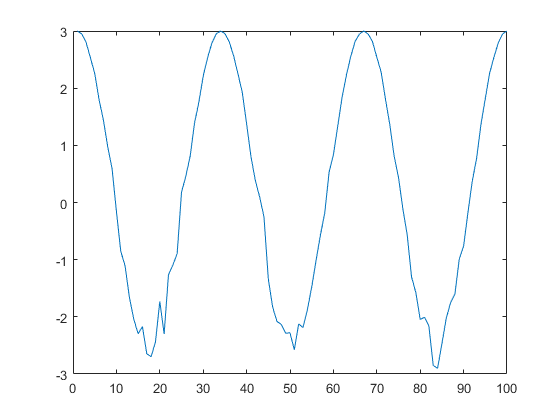

plot(res_vec)

               * La gràfica esbastant similar a el comportament d'un cosinus*

## Exercise 3:

**Create** and **test** a function named **rotMat2Eaa** that given a rotation matrix returns its respective euler principal axis and angle.

Perform and show the results of the next verifications:

- Use the function on exercise 1 to create a rotation matrix from Euler axis information and ensure that the new function performs the inverse mapping correctly.

res_axis=0;
res_ang=0;
[res_axis,res_ang]=rotMat2Eaa(r_mat)

res_axis =          0
         0
    1.0000


res_ang = 0.7854

- What happens if you try to extract the angle and axis of the next matrices? What they have in common? 


$$\mathbf{R}_1 = \left( \begin{array}{ccc} 1 &0 &0\\ 0 &1&0 \\0 &0 & 1\end{array}\right),$$

$$\mathbf{R}_2 = \left( \begin{array}{ccc} -\frac{1}{3} &\frac{2}{3} &\frac{2}{3}\\ \frac{2}{3} &-\frac{1}{3}&\frac{2}{3} \\\frac{2}{3} &\frac{2}{3} & -\frac{1}{3}\end{array}\right),$$

$$\mathbf{R}_3 = \left( \begin{array}{ccc} 0 &0 &-1\\ 0 &-1&0 \\-1 &0 & 0\end{array}\right),$$


*            Comment here and include code if you need it.*

- Propose a solution for the past problem, **implement it** and verify that it works using the past matrices

*Solution here : *

## Exercise 4

**Find the rotation vectors** that rotates the cube to reach the next orientations:

- The green face points in the positive z direction and the orange face in the -y direction

-     $$r_1 = $$ ( , , )$$^T$$

- The orange face points in the -z direction and the blue face into the +y direction

-     $$r_2 = $$ ( , , )$$^T$$

- The red face points on the -x direction and the blue face into the -y direction

-     $$r_3 = $$ ( , , )$$^T$$

Use the function of the exercise 1 transform the orientation of the cube given by M for **every** of the previous cases and use the function  Cubeplot to  verify your previous answers

M = [    -1  -1 1;   %Node 1
    -1   1 1;   %Node 2
    1   1 1;   %Node 3
    1  -1 1;   %Node 4
    -1  -1 -1;  %Node 5
    -1   1 -1;  %Node 6
    1   1 -1;  %Node 7
    1  -1 -1]; %Node 8


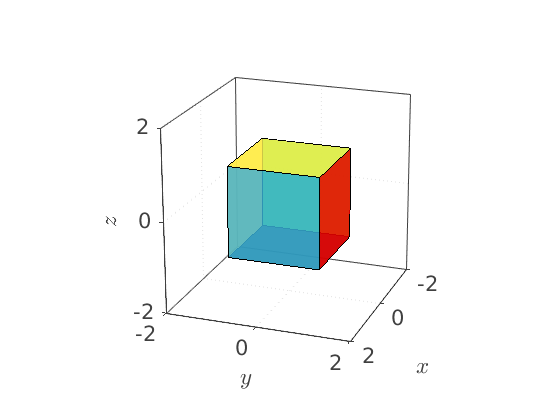

R = eye(3);
M_mod = (R*M')';
Cubeplot(M_mod);

## Exercise 5

**Create** and **test **a function named **eAngles2rotM **that given a set of euler angles $(\varphi, \theta, \psi)$, return its respective rotation matrix.

- Calculate the determinant of the resulting rotation matrix 

- Compare the transpose and the inverse of the resulting matrix

**Create also** a function named **rotM2eAngles **that given a rotation matrix return its respective euler angles

- Ensure that the case for which theta = pi/2 + k*pi with k=1,2,.. is well implemented

- Use the first function of this exercise to create a rotation matrix from a set of euler angles and ensure that the new function performs the inverse mapping correctly.